# Local parameter estimation for the 2019-2020 COVID-19 outbreak

This file explores a method for the local estimation of parameters for COVID-19 case counts in the US. 

Author: Joceline Lega. Date created: 7/21/2020. Last modified: 7/30/2020.

## Local parameter estimation

The best ICC curve parameters are found by minimizing the distance between the ICC curve and a smoothed and interpolated version of the data points. The search is done with MATLAB's `fminsearch`, with initial condition corresponding to $\beta = \gamma = 1,$ $N = 2 C_e,$ and $C_0 = C_e,$ where $C_e$ is the last data point in the smoothed dataset.

The first lines of code define the path to source data file.

clear variables;
% Read data file
location_name='AZ'; dataset_date='6-19';
pathname=['../../covid_state_hosp_data_' dataset_date '/'];

Parameter estimation is performed using data points between $d - n_{pts}$ and $d,$ where $d$ is a date specified by the user and $n_{pts}$ is the number of points used before the specified date.

% Define region of dataset to use
dt='06/05/2020'; n_pts=14;

The call to `find_best_ICC_fit` returns the best parameters (`X`) as well as the data points used for the parameter estimation.

[X,C_raw,I_raw,C,I] = ...
    find_best_ICC_fit(dt,n_pts,location_name,pathname);

## Plots

The figures shows the smoothed data points used for the fit (stars), the actual data points (triangles), the smoothed data for the entire dataset, and the ICC curve that best fits the selected data points. 

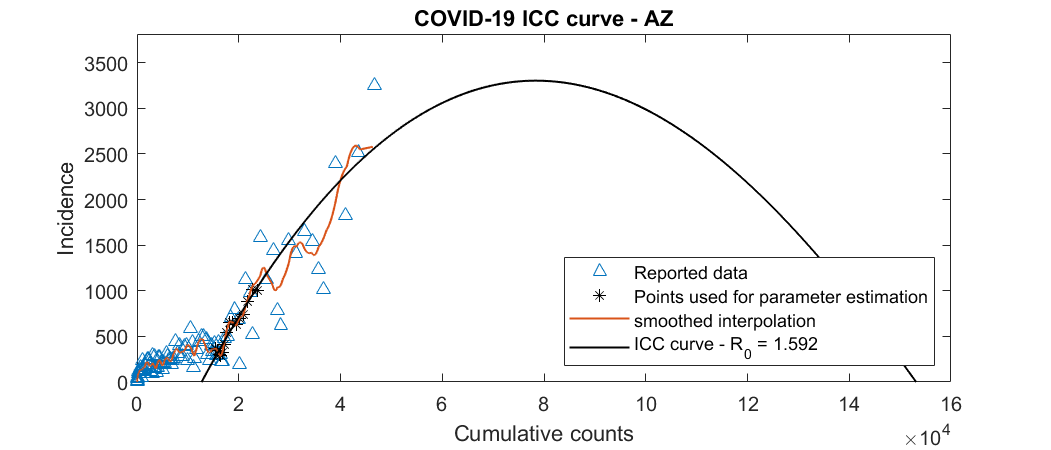

% Smooth and interpolate entire dataset
[~,~,~,C_o_raw,I_o_raw,~,~,C_o_ref,In_o_ref,~,~] = ...
    plot_ICC_curve(location_name,pathname,6,0,1,0,datenum('01/01/2020'),...
    datenum('12/31/2020'));
figure(); set(gcf,'Position',[0 0 700 300]);
plot(C_o_raw,I_o_raw,'^',C(end-n_pts:end),I(end-n_pts:end),'k*'); hold on;
plot(C_o_ref,In_o_ref,'-','LineWidth',1);
xlabel('Cumulative counts');
xx=1:X(3)/1000:X(3); yy=ICC(0,xx,X(1)^2,X(2)^2,X(3),X(4));
plot(xx,yy,'k-','LineWidth',1);
hold off;
MI=round(1.05*max([max(I) max(I_raw) max(yy)]));
ylim([0 1.1*MI]);
ylabel('Incidence'); title(['COVID-19 ICC curve - ' ...
    location_name ])
legend('Reported data','Points used for parameter estimation',...
    'smoothed interpolation', ['ICC curve - R_0 = ' num2str(X(1)^2/X(2)^2)],...
    'Location','southeast')